## **Tutorial 1: Row-reduction**

In this tutorial you will learn how to use matlab commands to perform row reduction. You will also see how row reduction is used in engineering and learn what Matlab's logo really is.

### Row reduction in Matlab

Matlab's command for row reduction is *rref*. You can find out how to use Matlab commands by typing help followed by the command.

help rref

Using rref on a matrix **A** gives the row echolon form of the matrix **A**. Here is an exmple.

A = [2 -1  1
     1  2  3
     3  0 -1];
 rref(A)

We encountered row reduction when silving linear equations$\mathbf{Ax}=\mathbf{b}$, where **A **is a n x n matrix and where **x** and **b** are n x 1 vectors. The goal is usually to find **x** given **A** and **b**. We can use rref to solve linear equations by appending the right-hand-side **b** to the matrix **A**. In Matlab, this means that you use rref on the matrix [**A b**]. Here is an example

b = [8
     9
     3];
 
rref([A b])     

You can now read the solution from the reduced row echolon form:

x = [2 
    -1
     3];

You can check this by computing Ax - b (which should be zero since Ax = b)

 A*x-b

Another command that you can use to solve **Ax** = **b** is the backslash: \ 

To solve **Ax**=**b**, this means that you compute x = A\b. Try it:

xhat = A\b

It looks like the command found the same solution. Let's check by computing A*xhat-b (which should be zero)

A*xhat-b

As you can see, this is not zero, but very near zero. Why? 

The answer is numerical error. When using "\" to solve linear equations, Matlab uses numerical methods, which introduce numerical error. This numerical error is small, if the numerical methods are appropriate (as they should be in Matlab). Small means that the errors are on the order of 10^(-15), which is the "machine precision," i.e., your computer cannot distinguish the number 0.00000000000000001 from 0. You can think of this as a precision: the computer only knows numbers up to 16 digits, what happens after the 16th digit irrelevant. And the numbers 0.00000000000000001 and 0 are the same for the first 16 digits.

And why is this different from what we got by rref?

When we used rref we obtained the vector (2 -1 3) from the row reduced [A b]. We typed in the numbers 2, -1 and 3 as the elements of this vector and this is the solution of Ax = b at an arbitrarily high precision (you could have come to this answer using pen and paper and without numerical methods). 

Let's try this on another example.

A = [-10  4
      15 -6];
b = [1
     0];
xhat= A\b  

Check the answer: 

A*xhat

As you can see, the numerical solution is inaccurate. Multiplying the numerical solution by **A** does not get us even close to the vector **b**.

Maybe we can explain this by using rref.

rref([A b])

The last row says that 0 = 1, which is not true. Using row-reduction, rather than "\" thus tells us that this system of equations does not have a solution, i.e., there is no **x** such that **Ax** = **b**. 

### Row reduction in action: what is Matlab's logo?

Before we get to Matlab's logo, we consider a simple mechanical system, consisting of two small carts, connected by a spring to each other and connected by two springs to the walls to the left and right. The situation is depicted in this figure:

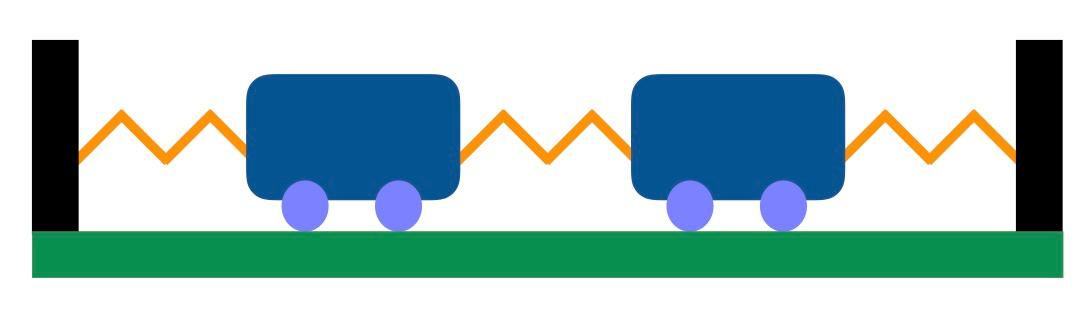

One can use Newton's laws to find a mathematical description of the motion of the two carts. Newton's laws also tell us that such a system has "preferred" motions, called "eigenmodes" (or characteristic modes). For the system with the two carts, the two eigenmodes describe two different types of motion. In mode 1, the two carts are in sync, whereas they are precisely out of sync in the second eigenmode.

All this can be discovered by row reduction. The mechanical system is described by two coordinates, x_1 and x_2, with x_1 describing the motion of the left cart and x_2 describing the motion of the right cart. We can combine x_1 and x_2 into a vector **x** = (x_1 x_2). The system is also characterized by a mass matrix **M** and a stiffness matrix **K**, which describe how heavy the carts are and how stiff the springs are. Assuming that both masses are equal and that all springs are the same, the mass and stiffness matrices are:

M = [1 0 
     0 1];
K = [2 -1
    -1  2];

The first eigenmode is now described by the linear system (**-M**+**K**)**x** = **0** (you will learn why in a physics class). We can use rref to find **x:**

rref([-M+K zeros(2,1)])

Note that we have a free variable (see the row of zeros). This means that x_2 can be set to 1, which then forces x_1 = 1. The solution is thus **x** = (1 1). The physical interpretation is that x_1 = x_2, i.e., the motion of the left cart is the same as the motion of the right cart. Put differently, the carts are "in sync".

The second eigenmode is now described by the linear system (**-3M**+**K**)**x** = **0** (you will learn why in a physics class). We can use rref to find **x:**

rref([-3*M+K zeros(2,1)])

Again, we have a free variable (see the row of zeros) and can set x_2 = 1, which then forces x_1 = -1. The solution is thus **x** = (-1 1). The physical interpretation is that x_1 = -x_2, i.e., the motion of the left cart is opposite to the motion of the right cart. Put differently, the carts are "out of sync".

The Matlab logo is also an eigenmode, but not of a cart-spring system, but of a membrane, i.e., a thin sheet of elastic material. The membrane is L-shaped and fixed at each of its corners as well as along two of the shorter eges, as is illustrated in this figure:

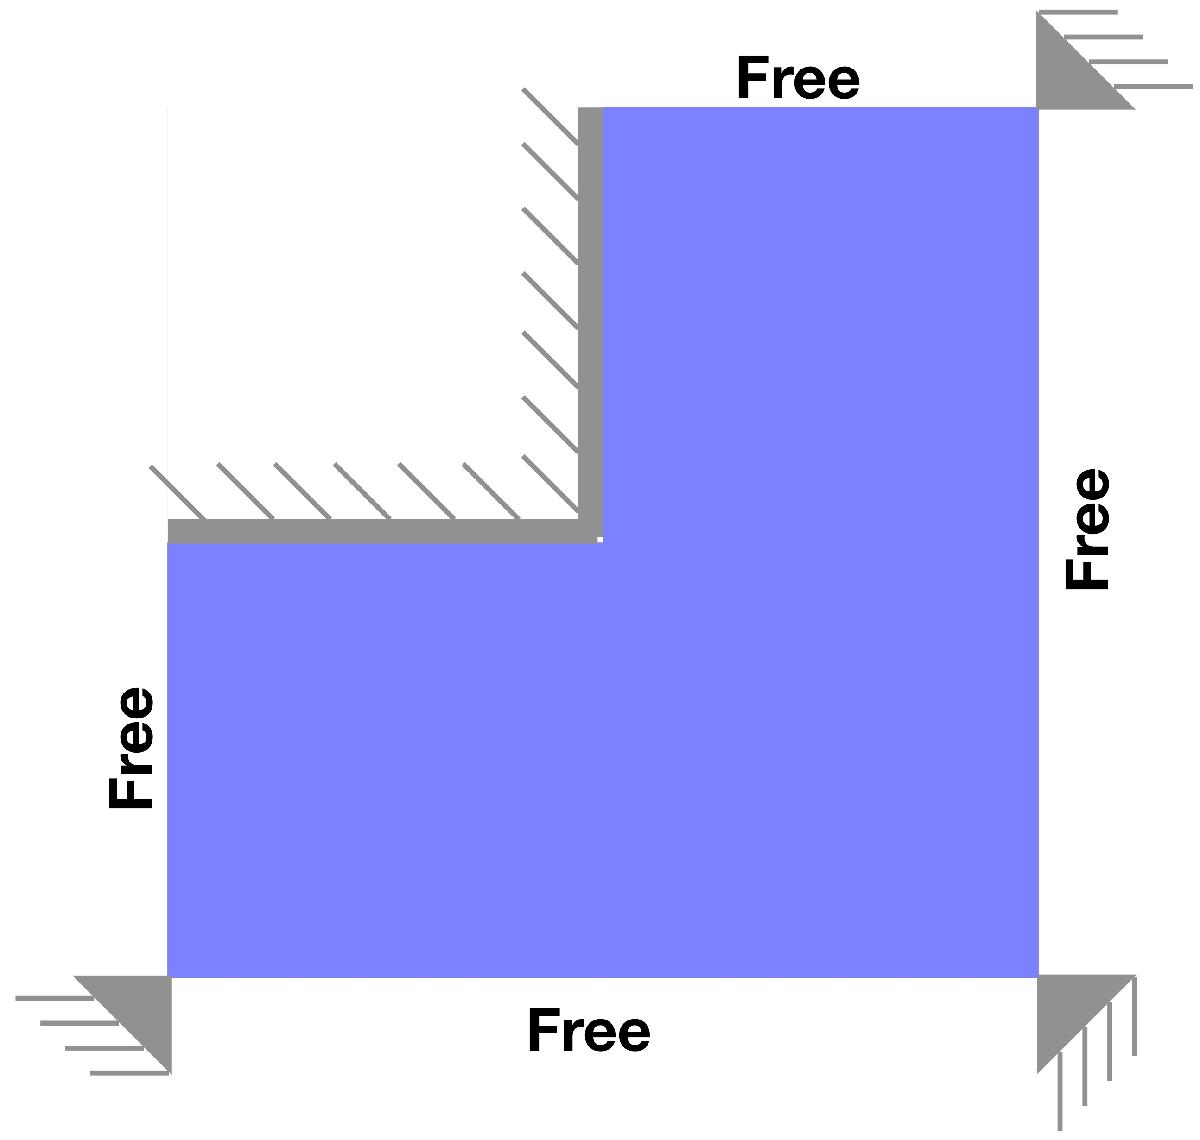

The mass and stiffness matrices describing the dynamic properties of the membrane are much bigger than the 2x2 example with the two masses, but the overall ideas are the same. One can in fact approximate the dynamic properties of the membrane by (a large number of) interconnected springs and masses and use the same techniques as above to find eigenmodes. The membrane has many eigenmodes, but Matlab's logo is the first eigenmode of the membrane. You can load the first eigenmode using the command

L = membrane(1);

This is essentially the result of doing row reduction on a very large matrix (961 x 961 in this case). 

You can plot the eigenmode using these commands.

s = surface(L);
s.EdgeColor = 'none';
view(3)

What you see is a typical dynamic shape the membrane takes on when set in motion.

You can see other modes, by setting L = membrane(); to a different number. For example, this code loads and shows you the second eigenmode.

L = membrane(2);

s = surface(L);
s.EdgeColor = 'none';
view(3)

You can experiment and load and plot higher eigenmodes. Do you notice anything about the modes as their number increases?

### Exercises

1. Use either rref or "\" to solve the linear equations **Ax** = **b** with 

A = [1 -3 -5
     0  1  -1];
b = [0
    -1];

Check your answer by computing **Ax**. Is **Ax** = **b**?

***Solution***

rref([A b])

Thus: $x_2 = x_3-1$ and $x_1 = 8x_3-3$. Setting $x_3=1$ gives

x = [5
     0
     1];
A*x

The backslash gives:

xhat = A\b
A*xhat

2. Use either rref or "\" to solve the linear equations **Ax** = **b** with 

A = [ 1 -2 -1  3
     -2  4  5 -5
      3 -6 -6  8];
     
b = [0
     3
     2];

Check your answer by computing **Ax**. Is **Ax** = **b**?

***Solution***

 rref([A b])

This equation has no solution.

Backslash gives:

 xhat = A\b;
 A*xhat

The backslash computes a numerically inaccurate answer.

3. Use either rref or "\" to solve the linear equations **Ax** = **b** with 

A = [1 2
     1 2];
b = [1
     1]; 

Check your answer by computing **Ax**. Is **Ax** = **b**?

***Solution***

 rref([A b])

Thus: $x_1 = 1-2x_2$, setting $x_2=1$ gives

 x = [-1
       1];
 A*x  

Using the backslash gives:

 xhat = A\b

This strange answer is because this equation has many solutions.